f = @(x) -x(1)^4 - 2*x(2)^4 - x(3)^4 - x(1)^2*x(2)^2 ...
    - x(1)^2*x(3)^2

f = function_handle with value:
    @(x)-x(1)^4-2*x(2)^4-x(3)^4-x(1)^2*x(2)^2-x(1)^2*x(3)^2


a1 = @(x) x(1)^4 + x(2)^4 + x(3)^4 - 25

a1 = function_handle with value:
    @(x)x(1)^4+x(2)^4+x(3)^4-25


a2 = @(x) 8*x(1)^2 + 14*x(2)^2 + 7*x(3)^2 - 56

a2 = function_handle with value:
    @(x)8*x(1)^2+14*x(2)^2+7*x(3)^2-56


ax = @(x) [a1(x); a2(x)]

ax = function_handle with value:
    @(x)[a1(x);a2(x)]


syms x1 x2 x3 lam1 lam2

xs0 = [x1; x2; x3]; lams0 = [lam1; lam2];
As = jacobian(ax(xs0), xs0)

$$As = \left(\begin{array}{ccc} 4\,{x_{1}}^{3} & 4\,{x_{2}}^{3} & 4\,{x_{3}}^{3}\\ 16\,x_{1} & 28\,x_{2} & 14\,x_{3} \end{array}\right)$$

rd = -gradient(f(xs0), xs0) + As'*lams0

$$rd = \left(\begin{array}{c} 4\,{x_{1}}^{3}+2\,x_{1}\,{x_{2}}^{2}+2\,x_{1}\,{x_{3}}^{2}+4\,{\mathrm{lam}}_{1}\,{\left(\bar{x_{1}}\right)}^{3}+16\,{\mathrm{lam}}_{2}\,\bar{x_{1}}\\ 2\,{x_{1}}^{2}\,x_{2}+8\,{x_{2}}^{3}+4\,{\mathrm{lam}}_{1}\,{\left(\bar{x_{2}}\right)}^{3}+28\,{\mathrm{lam}}_{2}\,\bar{x_{2}}\\ 2\,{x_{1}}^{2}\,x_{3}+4\,{x_{3}}^{3}+4\,{\mathrm{lam}}_{1}\,{\left(\bar{x_{3}}\right)}^{3}+14\,{\mathrm{lam}}_{2}\,\bar{x_{3}} \end{array}\right)$$

Ws = hessian(f(xs0), xs0) + hessian(a1(xs0), xs0)*lams0(1) + ...
    hessian(a2(xs0), xs0)*lams0(2)

$$Ws = \left(\begin{array}{ccc} 16\,{\mathrm{lam}}_{2}+12\,{\mathrm{lam}}_{1}\,{x_{1}}^{2}-12\,{x_{1}}^{2}-2\,{x_{2}}^{2}-2\,{x_{3}}^{2} & -4\,x_{1}\,x_{2} & -4\,x_{1}\,x_{3}\\ -4\,x_{1}\,x_{2} & 28\,{\mathrm{lam}}_{2}+12\,{\mathrm{lam}}_{1}\,{x_{2}}^{2}-2\,{x_{1}}^{2}-24\,{x_{2}}^{2} & 0\\ -4\,x_{1}\,x_{3} & 0 & 14\,{\mathrm{lam}}_{2}+12\,{\mathrm{lam}}_{1}\,{x_{3}}^{2}-2\,{x_{1}}^{2}-12\,{x_{3}}^{2} \end{array}\right)$$

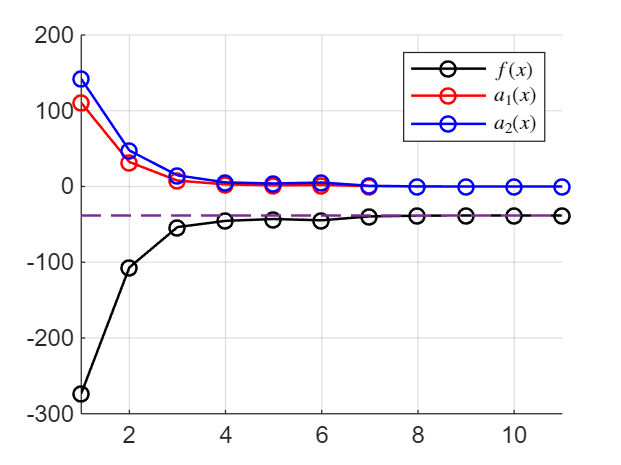

kmax = 100;
x = zeros(3, kmax);
lam = zeros(2, kmax);
x0 = [3, 1.5, 3]; x(:,1) = x0; lam0 = [1, 1]; lam(:,1) = lam0;
dx = 100*ones(3,1);
k = 1;

while (norm(dx) >= 1e-8) && (k <= kmax)
    [xnew, lamnew] = Qp(f, ax, x(:,k), lam(:,k), xs0);
    dx = x(:,k) - xnew;
    x(:,k+1) = xnew;
    lam(:,k+1) = lamnew;
    k = k + 1;
end
xp = x(:,1:k);
lamp = lam(:,1:k); 
N = size(xp, 2);
nv = 1:N;
a1p = zeros(1,N); a2p = zeros(1,N); fp = zeros(1,N);
for i = 1:size(xp,2)
    a1p(i) = a1(xp(:,i));
    a2p(i) = a2(xp(:,i));
    fp(i) = f(xp(:,i));
end
figure(1); clf;
hold on
plot(nv, fp,'ko-', 'LineWidth',1);
plot(nv, a2p,'ro-', 'linewidth', 1);
plot(nv, a1p, 'bo-', 'linewidth',1);
plot(nv, fp(end)*ones(1,N),'--', 'linewidth', 1);
grid;
axis([1,11, -300, 200]);
h1 = legend('$f(x)$', '$a_1(x)$', '$a_2(x)$');
set(h1, 'Interpreter','latex');
hold off

function [xnew, lamnew] = Qp(f, ax, x0, lam0, xs0 )
    aax = ax(xs0); a11 = aax(1); a22 = aax(2);
    gks = gradient(f(xs0), xs0);
    As = jacobian(ax(xs0), xs0);
    rds = -gradient(f(xs0), xs0) + As'*lam0;
    Ws = hessian(f(xs0), xs0) + hessian(a11, xs0)*lam0(1) + ...
        hessian(a22, xs0)*lam0(2);

    % change symbolic to numerical 
    Ak = double(subs(As, xs0, x0));
    rd = double(subs(rds, xs0, x0));
    rp = double(-ax(x0));
    gk = double(subs(gks, xs0, x0));
    Wk = double(subs(Ws, xs0, x0));

    % calculation step
    dz = [Wk Ak'; Ak zeros(size(Ak,1), size(Ak',2))]\[rd; rp];
    dx = dz(1:size(x0,1));
    lam = -Ak'\((Wk)*dx + gk);

    xnew = x0 + dx; lamnew = lam;
end